clear all;
close all;
colors=npg(100); 
init=[ 1 0 0 0 0 0];

init=init';
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');


%% Simulation parameters
time_resolution=0.001;

ham=2*pi*(1*sigmax+1*sigmax*sigmax);
ham_0=2*pi*12.8/5*sigmaz;
timelist=[0:time_resolution:10];
evo=ham.*(1.0/4).*1i;

atom_number=100;

%% FFT parameters

Fs = 100;            % Sampling frequency                    
T = 1/Fs;             % Sampling period   



%% factor=0.02 theta=0
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
factor=2*pi*0.02;% alpha_T/8F(2F-1)
theta=0

theta = 0


omega_x_squared=2*factor;
omega_y_squared=-2*(3*sin(theta)^2-1)*factor;
omega_z_squared=-2*(3*cos(theta)^2-1)*factor;

omega_yz=-3*2*sin(theta)*cos(theta)*factor;
omega_zy=-3*2*sin(theta)*cos(theta)*factor;

ham_l=omega_x_squared*sigmax*sigmax+omega_y_squared*sigmay*sigmay+omega_z_squared*sigmaz*sigmaz+omega_yz*sigmay*sigmaz+omega_zy*sigmaz*sigmay;

%%
k=1;
parfor i=1:length(timelist)
    evo_0=(ham_0+ham_l).*timelist(i).*1i;
    finalstate(:,i)=expm(-evo)*expm(-evo_0)*expm(-evo)*init;
end
%% Plot
finalpop(:,:)=abs(finalstate(:,:)).^2;
finalpop1=finalpop(1,:);
finalpop6=finalpop(6,:);
%sz=5./2.*finalpop(1,:)+3./2.*finalpop(2,:)+1./2.*finalpop(3,:)-1./2.*finalpop(4,:)-3./2.*finalpop(5,:)-5./2.*finalpop(6,:);
figure_1=figure('Position',[0 0 800 500])

figure_1 =   Figure (1) - 属性:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 800 500]
       Units: 'pixels'

  显示 所有属性


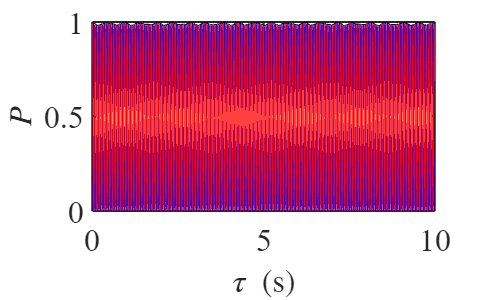


hold all

plot(timelist,finalpop1,'Color','blue')
plot(timelist,finalpop6,'Color','red')
plot(timelist,finalpop1+finalpop6,'Color','black')

%xlim([0 10])
ylim([0 1])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$P$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

%h1=breakxaxis([0.2 9.8]);

%% factor=0.02 theta=0
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
factor=2*pi*1;% alpha_T/8F(2F-1)
theta=0.01;

omega_x_squared=2*factor;
omega_y_squared=-2*(3*sin(theta)^2-1)*factor;
omega_z_squared=-2*(3*cos(theta)^2-1)*factor;

omega_yz=-3*2*sin(theta)*cos(theta)*factor;
omega_zy=-3*2*sin(theta)*cos(theta)*factor;

ham_l=omega_x_squared*sigmax*sigmax+omega_y_squared*sigmay*sigmay+omega_z_squared*sigmaz*sigmaz+omega_yz*sigmay*sigmaz+omega_zy*sigmaz*sigmay;

%%
k=1;
parfor i=1:length(timelist)
    evo_0=(ham_0+ham_l).*timelist(i).*1i;
    finalstate(:,i)=expm(-evo)*expm(-evo_0)*expm(-evo)*init;
end
%% Plot
finalpop(:,:)=abs(finalstate(:,:)).^2;
finalpop1=finalpop(1,:);
finalpop6=finalpop(6,:);
%sz=5./2.*finalpop(1,:)+3./2.*finalpop(2,:)+1./2.*finalpop(3,:)-1./2.*finalpop(4,:)-3./2.*finalpop(5,:)-5./2.*finalpop(6,:);
figure_1=figure('Position',[0 0 800 500])

figure_1 =   Figure (2) - 属性:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 800 500]
       Units: 'pixels'

  显示 所有属性


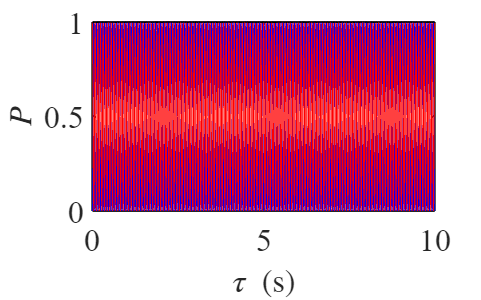


hold all

plot(timelist,finalpop1,'Color','blue')
plot(timelist,finalpop6,'Color','red')
plot(timelist,finalpop1+finalpop6,'Color','black')

%xlim([0 10])
ylim([0 1])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$P$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

%h1=breakxaxis([0.2 9.8]);


%% factor=0.00 

factor=2*pi*5.00;% alpha_T/8F(2F-1)
theta=0.1;
distribution=0.0;

omega_x_squared=2*factor;
omega_y_squared=-2*(3*sin(theta)^2-1)*factor;
omega_z_squared=-2*(3*cos(theta)^2-1)*factor;

omega_yz=-3*2*sin(theta)*cos(theta)*factor;
omega_zy=-3*2*sin(theta)*cos(theta)*factor;

ham_l=omega_x_squared*sigmax*sigmax+omega_y_squared*sigmay*sigmay+omega_z_squared*sigmaz*sigmaz+omega_yz*sigmay*sigmaz+omega_zy*sigmaz*sigmay;

ham_x=0.05*2*pi*12.8/5*sigmay;
%%
for ii=1:atom_number
    parfor i=1:length(timelist)
        evo_0=(ham_0+ham_l*(1+distribution*randn)+ham_x).*timelist(i).*1i;
        finalstate(ii,:,i)=expm(-evo)*expm(-evo_0)*expm(-evo)*init;
    end
end



finalpop(:,:,:)=abs(finalstate(:,:,:)).^2;

p1_average=squeeze(mean(finalpop(:,1,:),1));
p2_average=squeeze(mean(finalpop(:,2,:),1));
p3_average=squeeze(mean(finalpop(:,3,:),1));
p4_average=squeeze(mean(finalpop(:,4,:),1));
p5_average=squeeze(mean(finalpop(:,5,:),1));
p6_average=squeeze(mean(finalpop(:,6,:),1));
%
%sz=5./2.*p1_average+3./2.*p2_average+1./2.*p3_average-1./2.*p4_average-3./2.*p5_average-5./2.*p6_average;
%% FFT
figure_1=figure('Position',[0 0 800 500])

figure_1 =   Figure (33) - 属性:

      Number: 33
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 800 500]
       Units: 'pixels'

  显示 所有属性



hold all

plot(timelist,p1_average,'Color','blue')
plot(timelist,p6_average,'Color','red')
plot(timelist,p1_average+p6_average,'Color','black')

%xlim([0 10])
ylim([0 1])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$P$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)
h1=breakxaxis([0.2 9.8]);

annotationAxes =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1632 0.7750 0.7618]
            Units: 'normalized'

  显示 所有属性


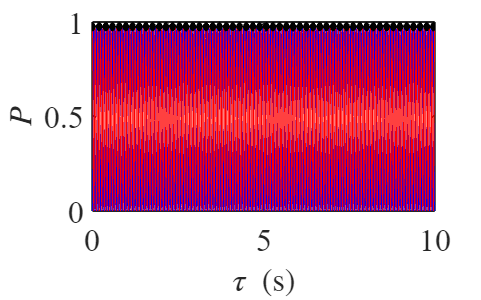

unbreakxaxis(h1);

%% factor=0.18 theta=magic
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
factor=2*pi*0.18;% alpha_T/8F(2F-1)
theta=acos(1/sqrt(3));

omega_x_squared=2*factor;
omega_y_squared=-2*(3*sin(theta)^2-1)*factor;
omega_z_squared=-2*(3*cos(theta)^2-1)*factor;

omega_yz=-3*2*sin(theta)*cos(theta)*factor;
omega_zy=-3*2*sin(theta)*cos(theta)*factor;

ham_l=omega_x_squared*sigmax*sigmax+omega_y_squared*sigmay*sigmay+omega_z_squared*sigmaz*sigmaz+omega_yz*sigmay*sigmaz+omega_zy*sigmaz*sigmay;

%%
k=1;
parfor i=1:length(timelist)
    evo_0=(ham_0+ham_l).*timelist(i).*1i;
    finalstate(:,i)=expm(-evo)*expm(-evo_0)*expm(-evo)*init;
end

无法执行赋值，因为左侧的大小为 100×1，右侧的大小为 6×1。

%% Plot
finalpop(:,:)=abs(finalstate(:,:)).^2;
finalpop1=finalpop(1,:);
sz=5./2.*finalpop(1,:)+3./2.*finalpop(2,:)+1./2.*finalpop(3,:)-1./2.*finalpop(4,:)-3./2.*finalpop(5,:)-5./2.*finalpop(6,:);
%% FFT
L = length(sz);             % Length of signal
t = (0:L-1)*T;        % Time vector
Y = fft(sz);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

figure_1=figure('Position',[0 0 800 500])

t = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');
ax1=nexttile(1,[1,2]);
plot(timelist,sz);
xlim([0 15])
ylim([-3 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$\langle S_z \rangle$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

ax1=nexttile(3,[1,1]);
plot(timelist,sz);
xlim([1 1.5])
ylim([-3 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$\langle S_z \rangle$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

ax1=nexttile(4,[1,1]);
plot(f,P1,'Linewidth',2,'Color',colors(5,:)) 
hold on
plot(f,P1,'.','Color',colors(1,:),'MarkerSize',10) 
xlim([9 11])
ylim([0 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('FFT','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
xlabel('Frequency (Hz)','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)
%ylim([0 1.05])
set(gca,'YScale','linear')

sz_5=sz;
P1_5=P1;

figure1=figure('Position',[0 0 800 1200])

figure1 =   Figure (11) - 属性:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 800 1200]
       Units: 'pixels'

  显示 所有属性


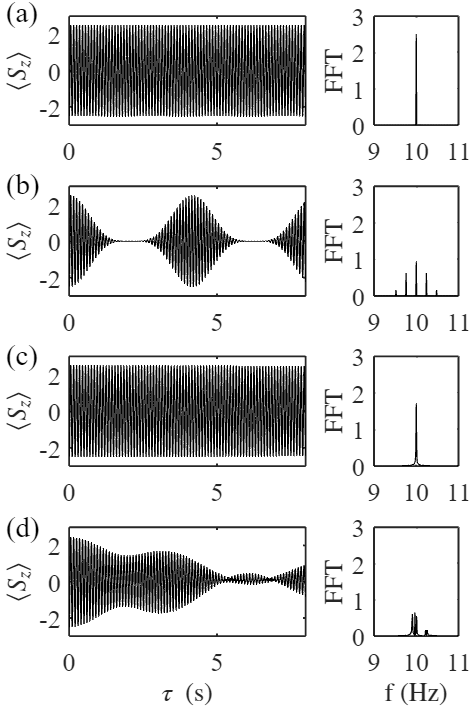


t = tiledlayout(4,3,'TileSpacing','compact','Padding','tight');

%%%%%%%%%%%%%%% first row
ax1_1=nexttile(1,[1,2]);
plot(timelist,sz_1,'k','LineWidth',1);
xlim([0 8])
ylim([-3 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$\langle S_z \rangle$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
%xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

ax1_2=nexttile(3,[1,1]);
plot(f,P1_1,'Linewidth',1,'Color',[0,0,0]) 
hold on
%plot(f,P1_1,'.','Color',[0,0,0],'MarkerSize',10) 
xlim([9 11])
ylim([0 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('FFT','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
%xlabel('Frequency (Hz)','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)
%%%%%%%%%%%%%%% second row
ax2_1=nexttile(4,[1,2]);
plot(timelist,sz_2,'k','LineWidth',1);
xlim([0 8])
ylim([-3 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$\langle S_z \rangle$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
%xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

ax2_2=nexttile(6,[1,1]);
plot(f,P1_2,'Linewidth',1,'Color',[0,0,0]) 
hold on
%plot(f,P1_1,'.','Color',[0,0,0],'MarkerSize',10) 
xlim([9 11])
ylim([0 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('FFT','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
%xlabel('Frequency (Hz)','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)
%%%%%%%%%%%%%%% third row
ax3_1=nexttile(7,[1,2]);
plot(timelist,sz_3,'k','LineWidth',1);
xlim([0 8])
ylim([-3 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$\langle S_z \rangle$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
%xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

ax3_2=nexttile(9,[1,1]);
plot(f,P1_3,'Linewidth',1,'Color',[0,0,0]) 
hold on
%plot(f,P1_1,'.','Color',[0,0,0],'MarkerSize',10) 
xlim([9 11])
ylim([0 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('FFT','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
%xlabel('Frequency (Hz)','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)
%%%%%%%%%%%%%%% fourth row
ax4_1=nexttile(10,[1,2]);
plot(timelist,sz_4,'k','LineWidth',1);
xlim([0 8])
ylim([-3 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('$\langle S_z \rangle$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
xlabel('$\tau\ (\mathrm{s})$','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

ax4_2=nexttile(12,[1,1]);
plot(f,P1_4,'Linewidth',1,'Color',[0,0,0]) 
hold on
%plot(f,P1_1,'.','Color',[0,0,0],'MarkerSize',10) 
xlim([9 11])
ylim([0 3])
box on
set(gca,'FontSize',22);
set(gca,'FontName','Times New Roman');
set(gca,'FontWeight','normal');
grid off
ylabel('FFT','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
xlabel('f (Hz)','Interpreter','latex', 'FontSize', 22,'FontName','Times New Roman')
set(gca,'LineWidth',1.5)

annotation(figure1,'textbox',...
    [0 0.97799511002445 0.0741043115438108 0.0354523227383864],...
    'String',{'(a)'},...
    'FontSize',24,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

% 创建 textbox
annotation(figure1,'textbox',...
    [0 0.735941320293399 0.0741043115438108 0.0354523227383864],...
    'String','(b)',...
    'FontSize',24,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

% 创建 textbox
annotation(figure1,'textbox',...
    [0 0.493887530562347 0.0741043115438108 0.0354523227383863],...
    'String','(c)',...
    'FontSize',24,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

% 创建 textbox
annotation(figure1,'textbox',...
    [0 0.251833740831296 0.0741043115438105 0.0354523227383866],...
    'String','(d)',...
    'FontSize',24,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');